clc
clear
close all

syms s
G = 1/(1000*s+500)

$$G = \frac{1}{1000\,s+500}$$

d = exp(-s*0.7)

$$d = {\mathrm{e}}^{-\frac{7\,s}{10}}$$

Gd = G*d

$$Gd = \frac{{\mathrm{e}}^{-\frac{7\,s}{10}}}{1000\,s+500}$$


G = tf(1,[1000 500], 'InputDelay', 0.7)

G =
 
                     1
  exp(-0.7*s) * ------------
                1000 s + 500
 
Continuous-time transfer function.



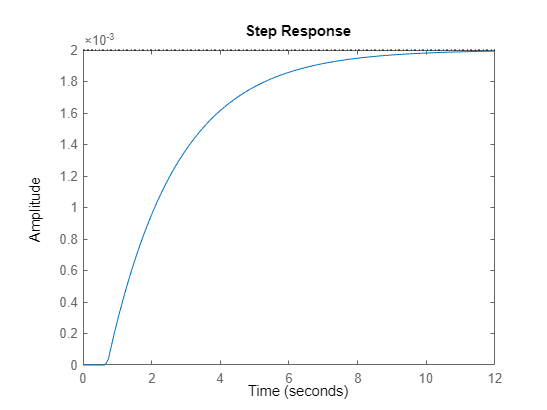


step(G)

stepinfo(step(G))

ans = struct with fields:
         RiseTime: 46.9022
    TransientTime: 89.4151
     SettlingTime: 89.4151
      SettlingMin: 0.0018
      SettlingMax: 0.0020
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0020
         PeakTime: 127



syms t

A = 2

A = 2


L = 0.7

L = 0.7000


tau = solve(2.8e-4/0.3 * (t - 0.7) == 2e-3, t)

$$tau = \frac{199}{70}$$

vpa(tau, 4)

$$ans = 2.843$$


R = A/tau

$$R = \frac{140}{199}$$

vpa(R, 3)

$$ans = 0.704$$


Kp = 1/(R*L)

Kp = 2

vpa(Kp, 4)

$$ans = 2.0$$


H = Kp/(1+(1000*s+500)*Kp)

$$H = \frac{2}{2000\,s+1001}$$


H = sym2tf(H, 0.7)

H =
 
                      2
  exp(-0.7*s) * -------------
                2000 s + 1001
 
Continuous-time transfer function.



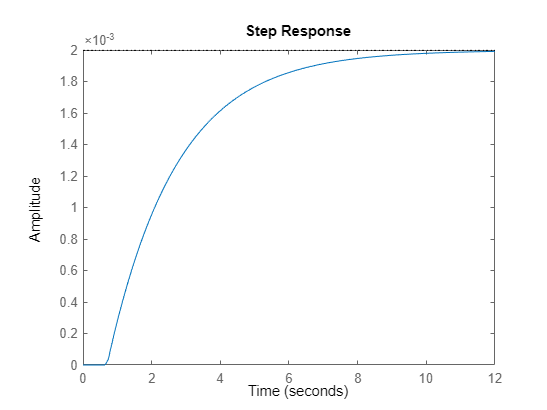


step(H)

function G = sym2tf(g, d)
    [n,m]=size(g);
    for i=1:n
        for j=1:m
            [num,den]=numden(g(i,j));
            num_n=sym2poly(num);
            den_n=sym2poly(den);
            G(i,j)=tf(num_n,den_n, 'InputDelay', d);
        end
    end
end